clc;
clear;
close all;
% ex3.a

N = 20;
P = 100000;
alfa = 0.9;
L = 1500;
C = 10;
f = 10000;
n = [10 20 30 40];

% variables for grah
PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));

PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

% variables for data
PLd = zeros(1, N);
PLv = zeros(1, N);
APDd = zeros(1, N);
APDv = zeros(1, N);
MPDd = zeros(1, N);
MPDv = zeros(1, N);
TT = zeros(1, N);

for i = 1:length(n)
    % Run the simulator N times
    for it = 1:N
            [PLd(it), PLv(it), APDd(it), APDv(it), MPDd(it), MPDv(it), TT(it)] = Sim3(L, C, f, P, n(i));
    end

    % Calculate Avg. Packet Delay for DATA packets
    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media
    APDd_terms(i) = term

    % Calculate Avg. Packet Delay for VoIP packets
    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media
    APDv_terms(i) = term

    % Calculate Packet Loss for DATA packets
    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media
    PLd_terms(i) = term

    % Calculate Packet Loss for VoIP packets
    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media
    PLv_terms(i) = term
end

APDd_values =     2.0061         0         0         0


APDd_terms = 1.0e-03 *

    0.8808         0         0         0


APDv_values =     1.6006         0         0         0


APDv_terms = 1.0e-03 *

    0.8430         0         0         0


PLd_values =     0.2295         0         0         0


PLd_terms = 1.0e-03 *

    0.8356         0         0         0


PLv_values =     0.0260         0         0         0


PLv_terms = 1.0e-03 *

    0.2640         0         0         0


APDd_values =     2.0061    2.3311         0         0


APDd_terms =     0.0009    0.0014         0         0


APDv_values =     1.6006    1.9318         0         0


APDv_terms =     0.0008    0.0014         0         0


PLd_values =     0.2295    0.4192         0         0


PLd_terms =     0.0008    0.0011         0         0


PLv_values =     0.0260    0.0520         0         0


PLv_terms = 1.0e-03 *

    0.2640    0.5160         0         0


APDd_values =     2.0061    2.3311    2.7125         0


APDd_terms =     0.0009    0.0014    0.0016         0


APDv_values =     1.6006    1.9318    2.3271         0


APDv_terms =     0.0008    0.0014    0.0016         0


PLd_values =     0.2295    0.4192    0.7515         0


PLd_terms =     0.0008    0.0011    0.0016         0


PLv_values =     0.0260    0.0520    0.0945         0


PLv_terms = 1.0e-03 *

    0.2640    0.5160    0.6272         0


APDd_values =     2.0061    2.3311    2.7125    3.2888


APDd_terms =     0.0009    0.0014    0.0016    0.0021


APDv_values =     1.6006    1.9318    2.3271    2.9255


APDv_terms =     0.0008    0.0014    0.0016    0.0022


PLd_values =     0.2295    0.4192    0.7515    1.4284


PLd_terms =     0.0008    0.0011    0.0016    0.0041


PLv_values =     0.0260    0.0520    0.0945    0.1900


PLv_terms = 1.0e-03 *

    0.2640    0.5160    0.6272    0.9152


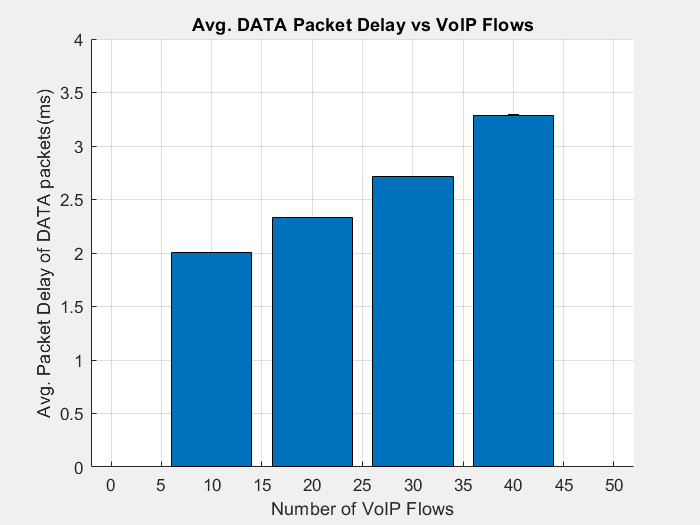


% Plot Avg. Packet Delay for DATA packets
figure(1);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDd_values');
ylim([0 4]);
er = errorbar(n, APDd_values', APDd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of DATA packets(ms)')
title('Avg. DATA Packet Delay vs VoIP Flows');
hold off;

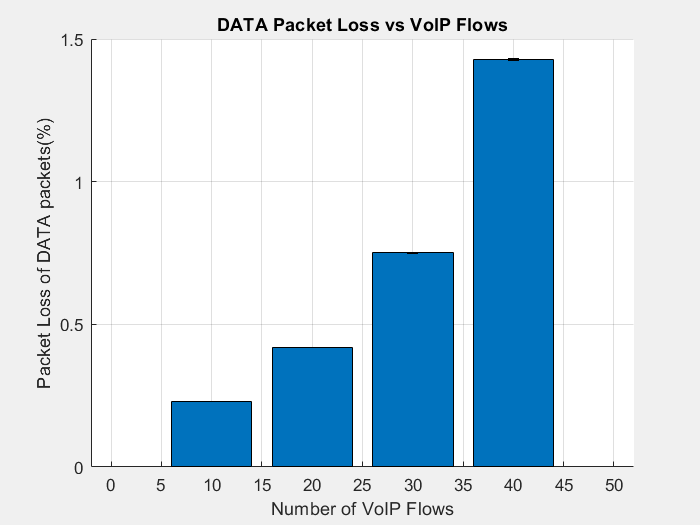


% Plot Avg. Packet Delay for VoIP packets
figure(2);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLd_values');
er = errorbar(n, PLd_values', PLd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of DATA packets(%)')
title('DATA Packet Loss vs VoIP Flows');
hold off;

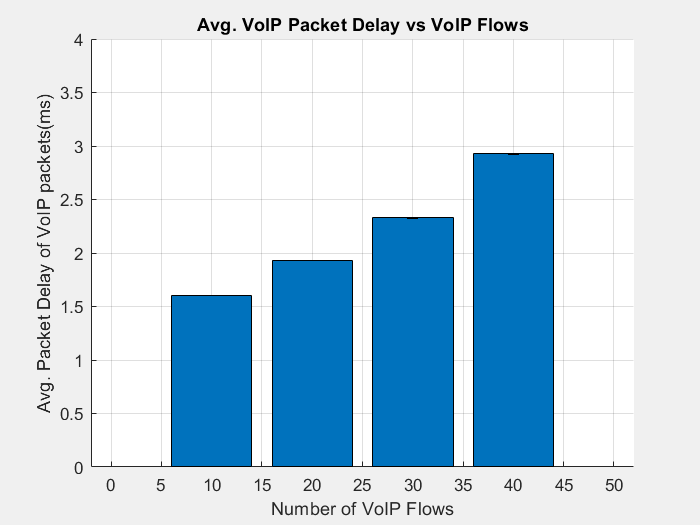


% Plot Packet Loss for DATA packets
figure(3);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDv_values');
ylim([0 4]);
er = errorbar(n, APDv_values', APDv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of VoIP packets(ms)')
title('Avg. VoIP Packet Delay vs VoIP Flows');
hold off;

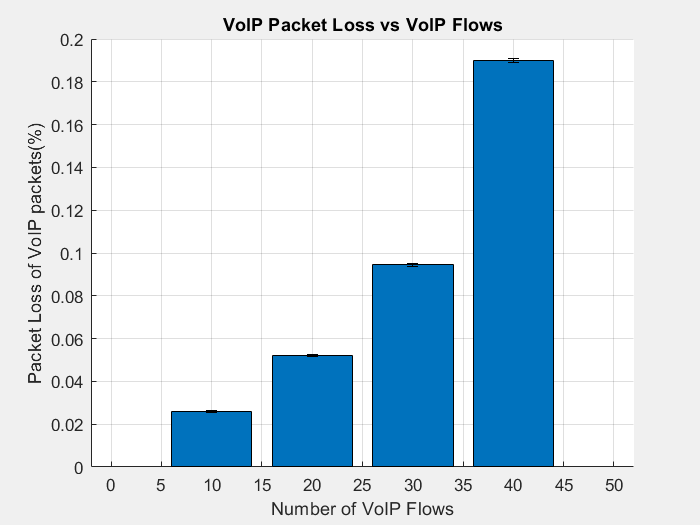


% Plot Packet Loss for VoIP packets
figure(4);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLv_values');
er = errorbar(n, PLv_values', PLv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of VoIP packets(%)')
title('VoIP Packet Loss vs VoIP Flows');
hold off;

clc;
clear;
close all;
% ex3.b

N = 20;
P = 100000;
alfa = 0.9;
L = 1500;
C = 10;
f = 10000;
n = [10 20 30 40];

% variables for grah
PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));

PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

% variables for data
PLd = zeros(1, N);
PLv = zeros(1, N);
APDd = zeros(1, N);
APDv = zeros(1, N);
MPDd = zeros(1, N);
MPDv = zeros(1, N);
TT = zeros(1, N);

for i = 1:length(n)
    % Run the simulator N times
    for it = 1:N
            [PLd(it), PLv(it), APDd(it), APDv(it), MPDd(it), MPDv(it), TT(it)] = Sim4(L, C, f, P, n(i));
    end

    % Calculate Avg. Packet Delay for DATA packets
    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media
    APDd_terms(i) = term

    % Calculate Avg. Packet Delay for VoIP packets
    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media
    APDv_terms(i) = term

    % Calculate Packet Loss for DATA packets
    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media
    PLd_terms(i) = term

    % Calculate Packet Loss for VoIP packets
    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media
    PLv_terms(i) = term
end

APDd_values =     2.0948         0         0         0


APDd_terms =     0.0011         0         0         0


APDv_values =     0.4606         0         0         0


APDv_terms = 1.0e-04 *

    0.8699         0         0         0


PLd_values =     0.2395         0         0         0


PLd_terms = 1.0e-03 *

    0.7787         0         0         0


PLv_values =     0.0278         0         0         0


PLv_terms = 1.0e-03 *

    0.3350         0         0         0


APDd_values =     2.0948    2.5336         0         0


APDd_terms =     0.0011    0.0015         0         0


APDv_values =     0.4606    0.4799         0         0


APDv_terms = 1.0e-04 *

    0.8699    0.7747         0         0


PLd_values =     0.2395    0.4478         0         0


PLd_terms =     0.0008    0.0012         0         0


PLv_values =     0.0278    0.0514         0         0


PLv_terms = 1.0e-03 *

    0.3350    0.3759         0         0


APDd_values =     2.0948    2.5336    3.0970         0


APDd_terms =     0.0011    0.0015    0.0019         0


APDv_values =     0.4606    0.4799    0.5017         0


APDv_terms = 1.0e-04 *

    0.8699    0.7747    0.7496         0


PLd_values =     0.2395    0.4478    0.7847         0


PLd_terms =     0.0008    0.0012    0.0023         0


PLv_values =     0.0278    0.0514    0.0909         0


PLv_terms = 1.0e-03 *

    0.3350    0.3759    0.4831         0


APDd_values =     2.0948    2.5336    3.0970    3.8747


APDd_terms =     0.0011    0.0015    0.0019    0.0033


APDv_values =     0.4606    0.4799    0.5017    0.5218


APDv_terms = 1.0e-04 *

    0.8699    0.7747    0.7496    0.9102


PLd_values =     0.2395    0.4478    0.7847    1.3594


PLd_terms =     0.0008    0.0012    0.0023    0.0037


PLv_values =     0.0278    0.0514    0.0909    0.1591


PLv_terms = 1.0e-03 *

    0.3350    0.3759    0.4831    0.5962


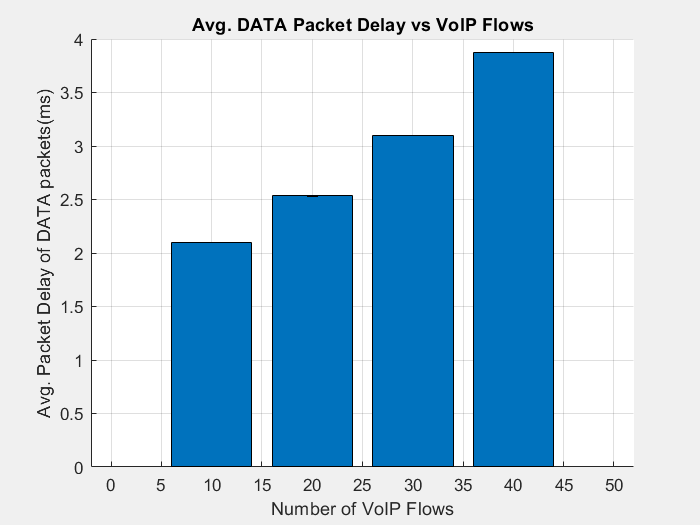


% Plot Avg. Packet Delay for DATA packets
figure(1);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDd_values');
ylim([0 4]);
er = errorbar(n, APDd_values', APDd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of DATA packets(ms)')
title('Avg. DATA Packet Delay vs VoIP Flows');
hold off;

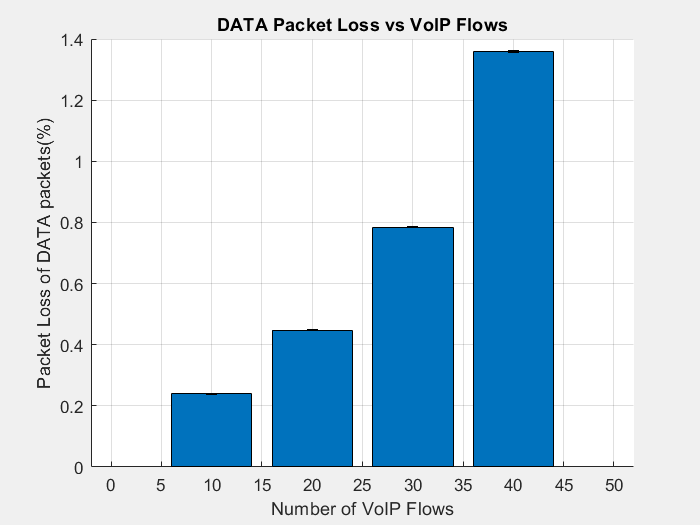


% Plot Avg. Packet Delay for VoIP packets
figure(2);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLd_values');
er = errorbar(n, PLd_values', PLd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of DATA packets(%)')
title('DATA Packet Loss vs VoIP Flows');
hold off;

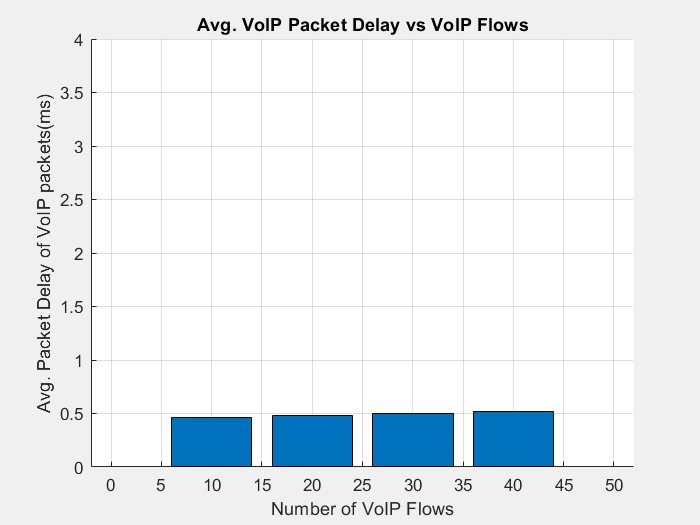


% Plot Packet Loss for DATA packets
figure(3);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDv_values');
ylim([0 4]);
er = errorbar(n, APDv_values', APDv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of VoIP packets(ms)')
title('Avg. VoIP Packet Delay vs VoIP Flows');
hold off;

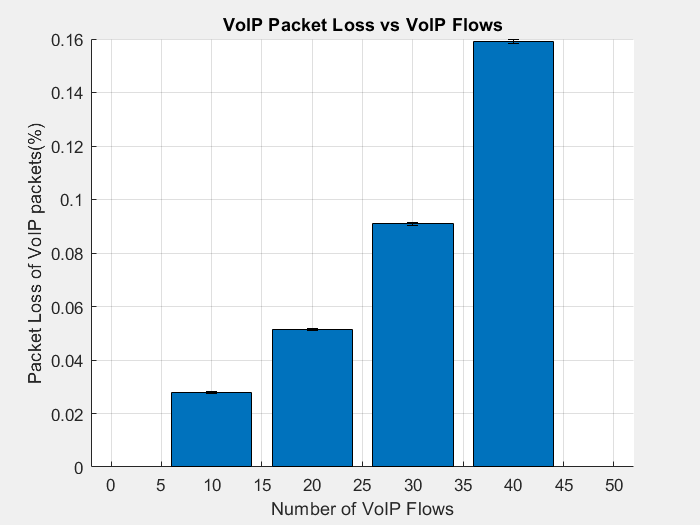


% Plot Packet Loss for VoIP packets
figure(4);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLv_values');
er = errorbar(n, PLv_values', PLv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of VoIP packets(%)')
title('VoIP Packet Loss vs VoIP Flows');
hold off;

#### 3.d)Use simulator Sim4A to estimate the same performance parameters as in 3.a and 3.b for p = 90%. Justify the differences in the performance values obtained for each service, and the differences between these results and the results of experiment 3.b. Draw all relevant conclusions.

N = 20;
P = 100000;
alfa = 0.1; % 90% confidence interval
L = 1500;
C = 10;
F = 10000;
n = [10 20 30 40];
p = 0.9;

PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));


PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

PLd = zeros(1,N);
APDd = zeros(1,N);
PLv = zeros(1,N);
APDv = zeros(1,N);


for i = 1:length(n)
    for x = 1:N
        [PLd(x),PLv(x),APDd(x),APDv(x),MPDd(x),MPDv(x),TT(x)] = Sim4A(L, C, F, P, n(i), p);
    end

    fprintf('For n = %d VoIP flows \n', n(i));
    
    % Calculate packet loss of data

    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media;
    PLd_terms(i) = term;
    fprintf('PacketLoss of data(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate packet loss of VoIP

    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media;
    PLv_terms(i) = term;
    fprintf('PacketLoss of VoIP(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of data

    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media;
    APDd_terms(i) = term;
    fprintf('Av. Packet Delay of data(ms)     = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of VoIP

    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media;
    APDv_terms(i) = term;
    fprintf('Av. Packet Delay of VoIP(ms)     = %0.2e +- %0.2e\n',media,term);
end

For n = 10 VoIP flows 


PacketLoss of data(%)             = 3.66e-01 +- 1.49e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 2.03e+00 +- 1.33e-02


Av. Packet Delay of VoIP(ms)     = 4.59e-01 +- 1.26e-03


For n = 20 VoIP flows 


PacketLoss of data(%)             = 6.10e-01 +- 2.77e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 2.40e+00 +- 1.62e-02


Av. Packet Delay of VoIP(ms)     = 4.78e-01 +- 1.02e-03


For n = 30 VoIP flows 


PacketLoss of data(%)             = 1.02e+00 +- 3.47e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 2.91e+00 +- 2.35e-02


Av. Packet Delay of VoIP(ms)     = 4.98e-01 +- 1.01e-03


For n = 40 VoIP flows 


PacketLoss of data(%)             = 1.66e+00 +- 4.73e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 3.55e+00 +- 3.22e-02


Av. Packet Delay of VoIP(ms)     = 5.17e-01 +- 1.25e-03


#### 3.e)Repeat experiment 3.d considering now p = 60%. Justify the differences in the performance values obtained for each service, and the differences between these results and the results of experiments 3.b and 3.d. Draw all relevant conclusions.

p = 0.6;

PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));


PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

PLd = zeros(1,N);
APDd = zeros(1,N);
PLv = zeros(1,N);
APDv = zeros(1,N);


for i = 1:length(n)
    for x = 1:N
        [PLd(x),PLv(x),APDd(x),APDv(x),MPDd(x),MPDv(x),TT(x)] = Sim4A(L, C, F, P, n(i), p);
    end

    fprintf('For n = %d VoIP flows \n', n(i));
    
    % Calculate packet loss of data

    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media;
    PLd_terms(i) = term;
    fprintf('PacketLoss of data(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate packet loss of VoIP

    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media;
    PLv_terms(i) = term;
    fprintf('PacketLoss of VoIP(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of data

    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media;
    APDd_terms(i) = term;
    fprintf('Av. Packet Delay of data(ms)     = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of VoIP

    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media;
    APDv_terms(i) = term;
    fprintf('Av. Packet Delay of VoIP(ms)     = %0.2e +- %0.2e\n',media,term);
end
